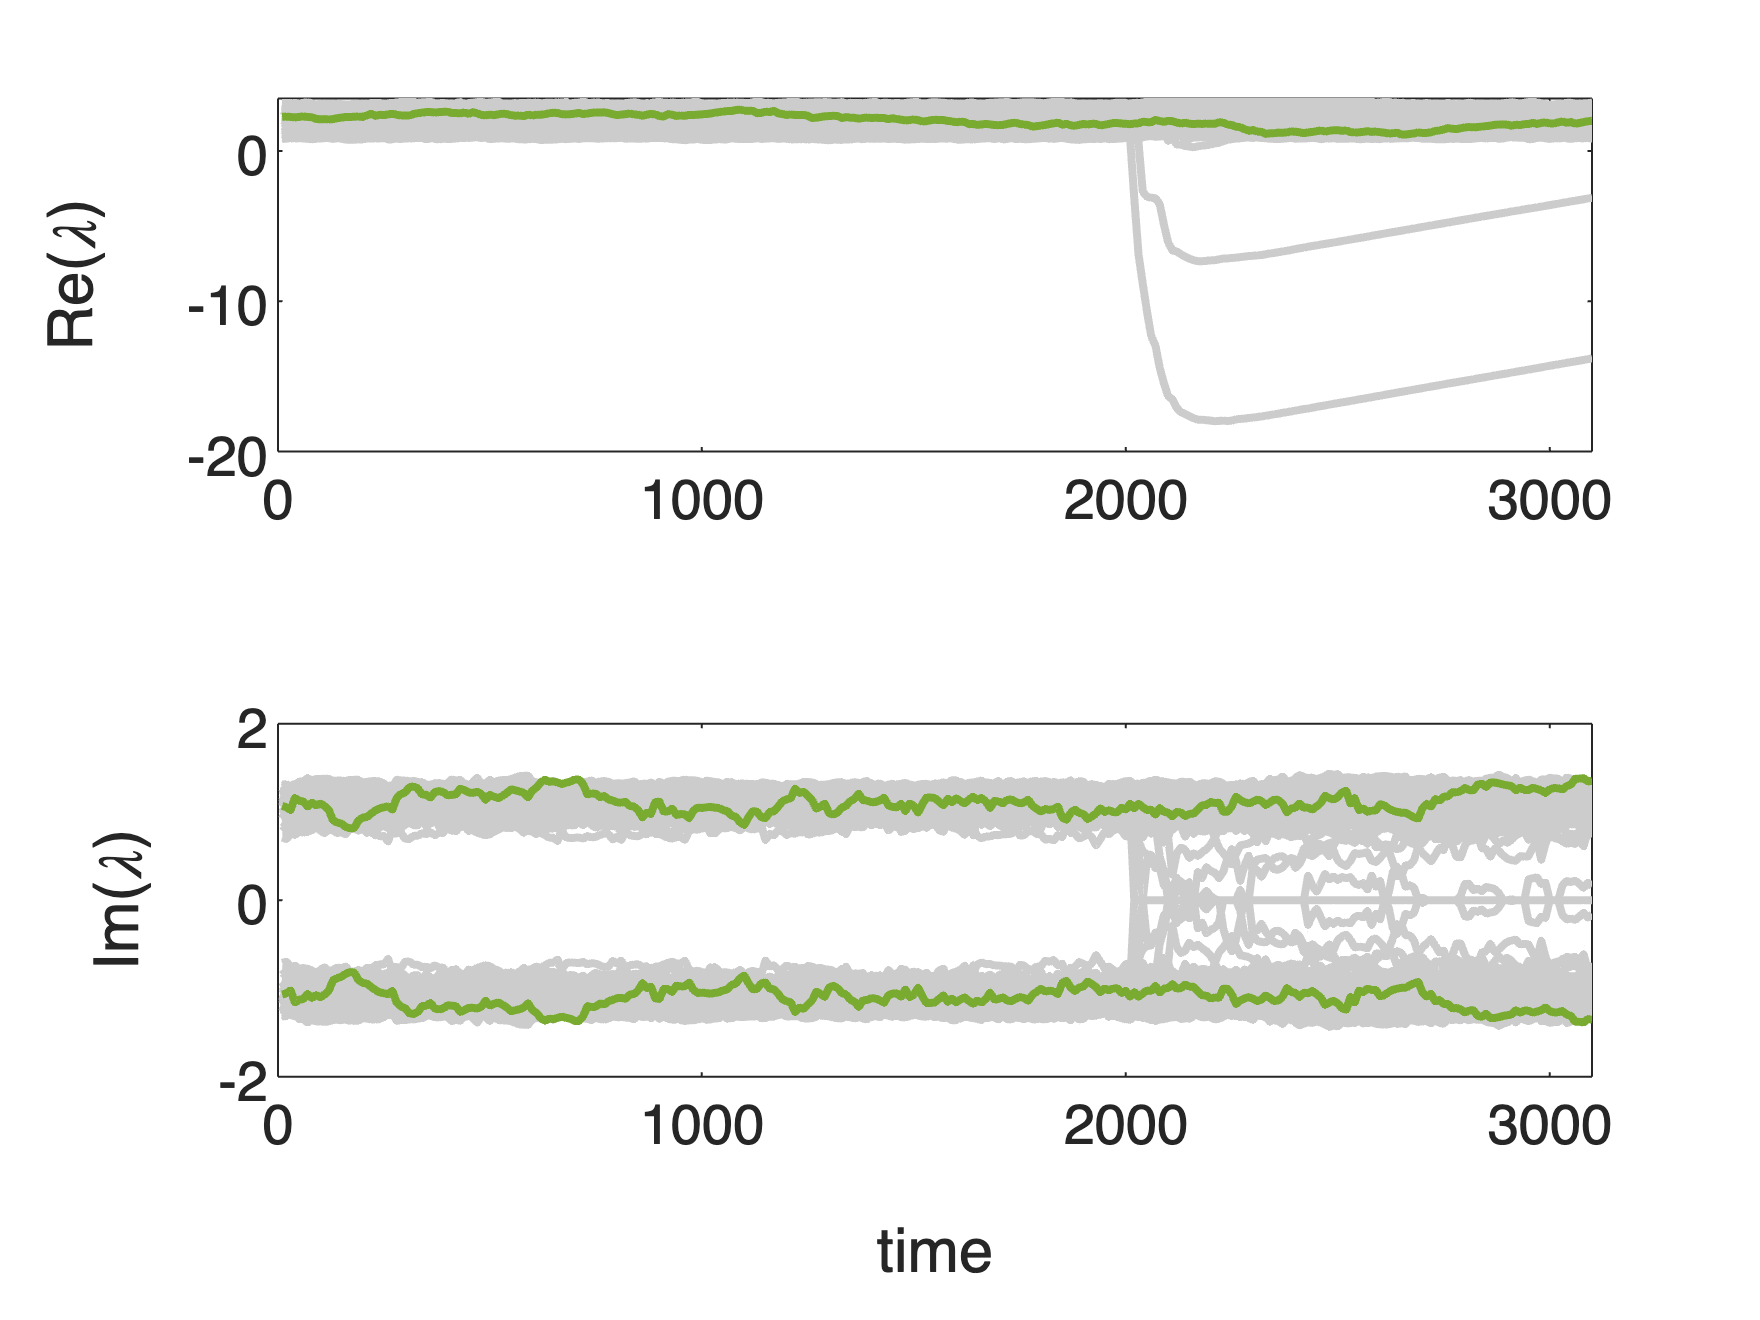

%  Simulate rate network with decorrelation homeostasis
%%%%  Load pre-initialized network
%%%%  Dynamically learn one memory item

clear variables; clc;
close all;

load('data');
seed = data.decseed;
rng(seed);
N = 128;
Nmem = 1; % number of memories to be store in the network
dt = .1;
eta = .01;
tau = 50;
taux = 20;
zeta = .01;
amp = 25;
inLen = 100/dt; % input length  
spacing = 1000/dt; % time spacing betweenn memories
spacing0 = 2000/dt; % initial time spacing
TotalSteps = spacing0 + (inLen + spacing)*Nmem;
CalcEvery = 10/dt;
Nsteps = TotalSteps/CalcEvery;

y = zeros(N,1);
z = zeros(N,1);
W_all = zeros(N,N,Nsteps);
x_all = zeros(N,TotalSteps);

H = sign(randn(N));
u = H(1:Nmem,:)'/sqrt(N);
v = H(Nmem+1:2*Nmem,:)'/sqrt(N);

input1 = zeros(N,TotalSteps);
input2 = zeros(N,TotalSteps);
input = zeros(N,1);
xlp = 0;
B = .5*eye(N); % ??? for some reason there is an extra factor of 0.5
W = data.W;
x = data.x;

f = waitbar(0,'Simulating, please wait...');

%%%% Construct input signal for learning
for i = 1:Nmem
    base = (i-1)*spacing + spacing0;
    input1(:,base+1:base+inLen) = repmat(u(:,i),1,inLen);
    input2(:,base+1:base+inLen) = repmat(v(:,i),1,inLen);
end

%%%% Evolve network
for i=1:TotalSteps
    
    if ~mod(i-1,CalcEvery)
        W_all(:,:,(i-1)/CalcEvery + 1) = W;
        waitbar((i-1)/TotalSteps,f,'Simulating, please wait...');
    end
    
    x_all(:,i) = x;
    r = tanh(x);
    xlp = ((-xlp + x/1e-2)/taux)*dt;
    input = input + (-zeta*input + randn*input1(:,i) + randn*input2(:,i))*dt;
    
    y = y + (r - y)*dt/tau;  
    x = x + (-x + W*r + amp*input)*dt;

    W = W + eta*((B - tanh(x - xlp)*tanh(x)' + randn(N)/sqrt(N)) + (r*y' - y*r'))*dt;
end

%%%% Compute eigenspectrum of W over time
[Vseq,Dseq] = eigenshuffle(W_all);
[~,I] = sort((imag(Dseq(:,end))),'descend');
Dsorted = Dseq(I,end);
taxis = [1:1:Nsteps]*CalcEvery*dt;

% %%%% Plot spectrum
for j=1:1:N
    figure(100); subplot(2,1,1); plot(taxis,real(Dseq(I(j),:)),'linewidth',2,'color',[1 1 1]*.8); hold on;
    figure(100); subplot(2,1,2); plot(taxis,imag(Dseq(I(j),:)),'linewidth',2,'color',[1 1 1]*.8); hold on;
end
subplot(2,1,2); plot(taxis,imag(Dseq(I(1),:)),'linewidth',2,'color',[.47 .67 .19]); hold on;
plot(taxis,imag(Dseq(I(end),:)),'linewidth',2,'color',[.47 .67 .19]);
xlabel('time'); ylabel('Im(\lambda)'); set(gca,'fontsize',14); 
subplot(2,1,1); plot(taxis,real(Dseq(I(1),:)),'linewidth',2,'color',[.47 .67 .19]); hold on;
plot(taxis,real(Dseq(I(end),:)),'linewidth',2,'color',[.47 .67 .19]); 
set(gca,'fontsize',14);ylabel('Re(\lambda)');


close(f);
